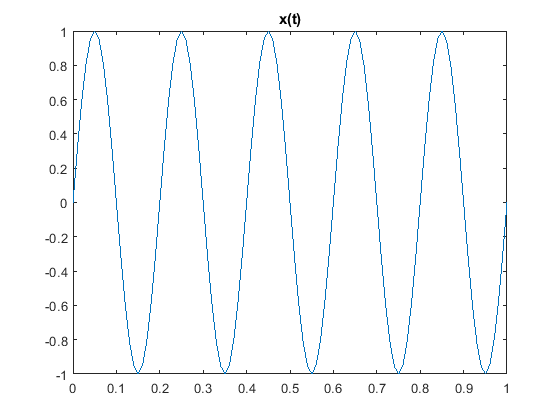

t = linspace(0,10,1000);
frequency = 5;
x = sin(2*pi*frequency*t);


figure()
plot(t, x)
title("x(t)")
xlim([0,1])

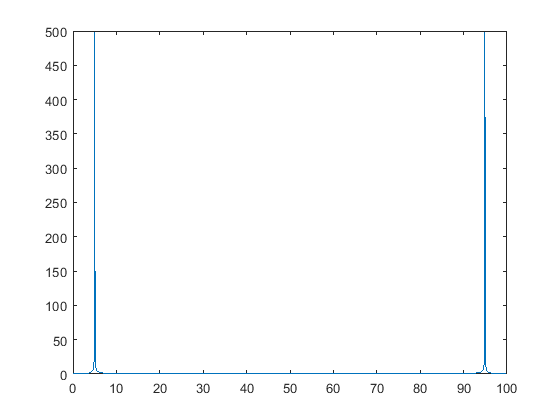

dftCalculator = DFTCalculator();
[freqs, spectrum] = dftCalculator.DFT(t, x);

figure()
plot(freqs, abs(spectrum))

[tInverse, sInverse] = dftCalculator.IDFT(freqs, spectrum);

figure()
plot(tInverse, sInverse)

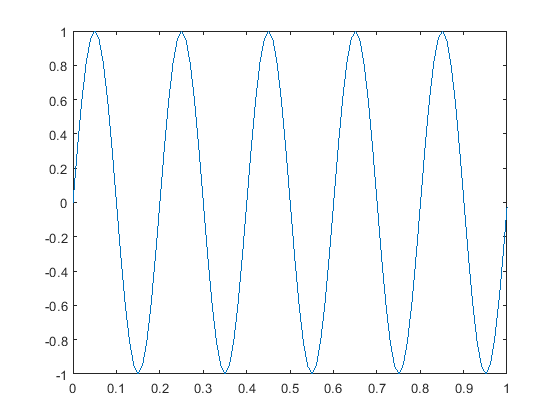

xlim([0,1])